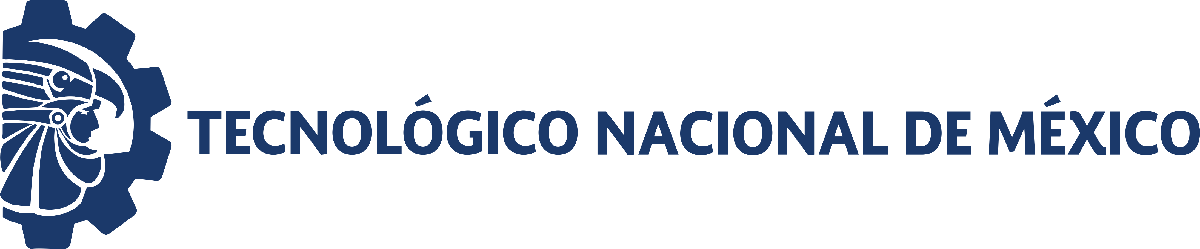                                 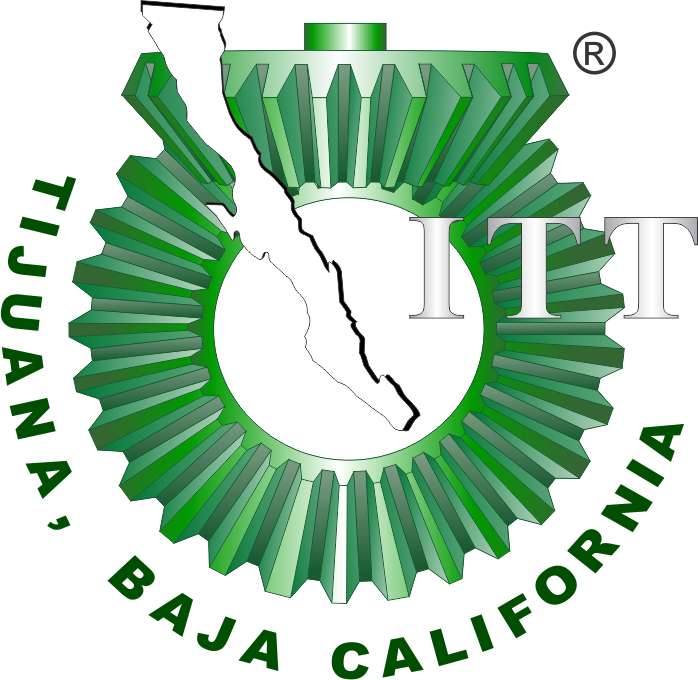

# Práctica: Liberación controlada de fármacos por hidrogeles

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Objetivo

Determinar la tasa de liberación del hidrogel N36 2MBA3 con base en los datos experimentales de la siguiente figura.

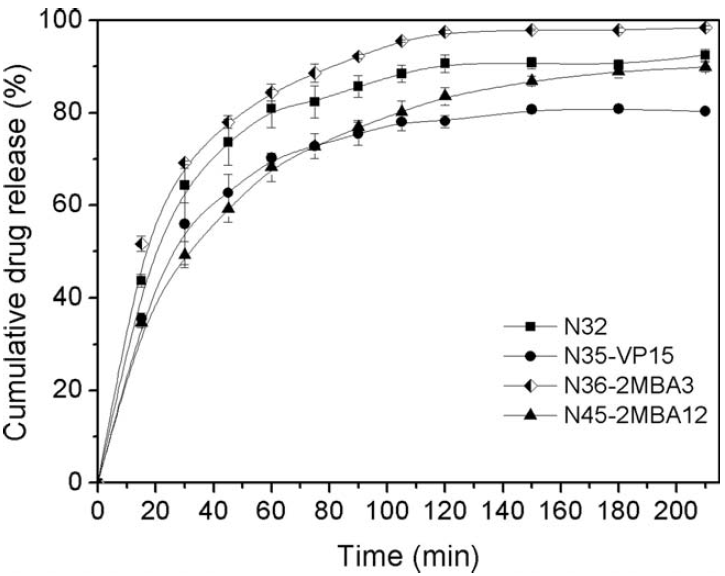

## Referencia

M. A. González‐Ayón, J.A. Sañudo‐Barajas, L.A. Picos‐Corrales, & A. Licea‐Claverie, "PNVCL‐PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5‐fluorouracil", *Journal of Polymer Science Part A: Polymer Chemistry*, vol. 53, issue 22, pp. 2662-2672, Aug 2015. DOI: [https://doi.org/10.1002/pola.27766](https://doi.org/10.1002/pola.27766)

## Modelos a ajustar a los datos experimentales

Ecuación de Peppas: $x\left(t\right)=kt^n$

Farmacocinética de primer orden: $$x(t) = \beta(1 - e^{-kt})$ $

Eureqa: $$x(t) = p_1t/(p_2+t)$ $

Eureqa EDO: $$\dot{x} = p_1-p_2x$ $

## Datos experimentales

    t [min]      N45        N32       N35       N36  
    _______    ________    ______    ______    ______

        0      0.009807    0.2398    0.1248    0.1248
       15        34.048    43.823    35.543    51.873
       30        48.883    64.407    56.012    69.352
       45        59.002    73.722    62.912    78.092
       60        67.972    80.966    70.157    84.071
       75        72.572    82.461    73.032    88.671
       90        76.942    85.911    75.562    92.351
      105        80.161    88.556    77.977    95.571
      120        83.381    90.856    78.437    97.641
      150        86.831    90.971    80.736    97.871
      180        88.901    90.741    80.966    98.101
      210        89.936    92.696    80.391    98.561



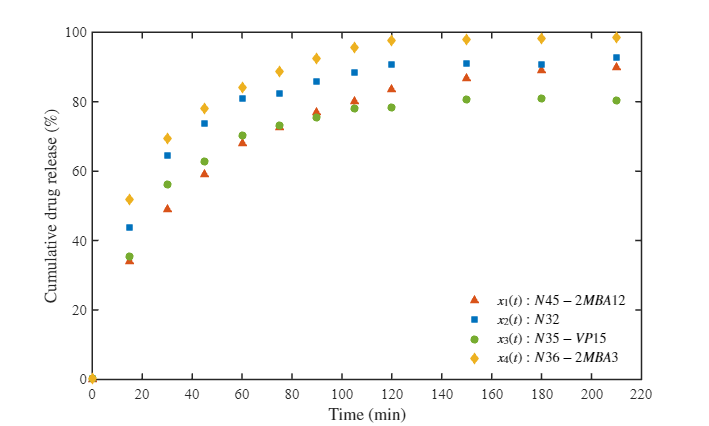

--> Gráfica exportada exitosamente como: data.pdf


clc; clear; close all; warning('off','all')
[t,x1,x2,x3,x4] = getdata('data.csv'); plotdata(t,x1,x2,x3,x4);

## Regresión no lienal, bioestadistios y experimentación in silico

labels = {'x1(t):N45-2MBA12', 'x2(t):N32', 'x3(t):N35-VP15', 'x4(t):N36-2MBA3'};
xo = [x1,x2,x3,x4]; s = size(xo);

### Función de Pepas

n0 = 0.1; k0 = 0.1; xp = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el hidrogel: ', string(labels(i))]);
    mdl = peppas(t,xo(:,i),[k0;n0]);
    xp(:,i) = mdl.Fitted; disp('');
end

    "Resultados para el hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        17.368       2.1669      4.8282      12.54     22.196    1.1583e-05
      {'n'}       0.32003     0.026562    0.059185    0.26084    0.37921    2.8132e-07

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9795
Suma residual de cuadrados:     162.4260
Criterio de inf. Akaike (AICc)

    "Resultados para el hidrogel: "    "x2(t):N32"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        30.531       4.2414      9.4505     21.081     39.982     2.932e-05
      {'n'}       0.22002     0.030062    0.066982    0.15304      0.287    2.5447e-05

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9639
Suma residual de cuadrados:     293.3973
Criterio de inf. Akaike (AICc)

    "Resultados para el hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE         MoE             CI95             Pvalue  
    __________    ________    ________    ________    _________________    __________

      {'k'}        24.851       3.8686      8.6197    16.231     33.471    7.5972e-05
      {'n'}       0.23545     0.033596    0.074856    0.1606    0.31031    3.6782e-05

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9575
Suma residual de cuadrados:     273.8092
Criterio de inf. Akaike (AICc): 76

    "Resultados para el hidrogel: "    "x4(t):N36-2MBA3"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        34.356       3.7899      8.4445     25.912     42.801    3.8779e-06
      {'n'}       0.20987     0.023914    0.053284    0.15659    0.26316    5.1868e-06

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9761
Suma residual de cuadrados:     217.2593
Criterio de inf. Akaike (AICc)

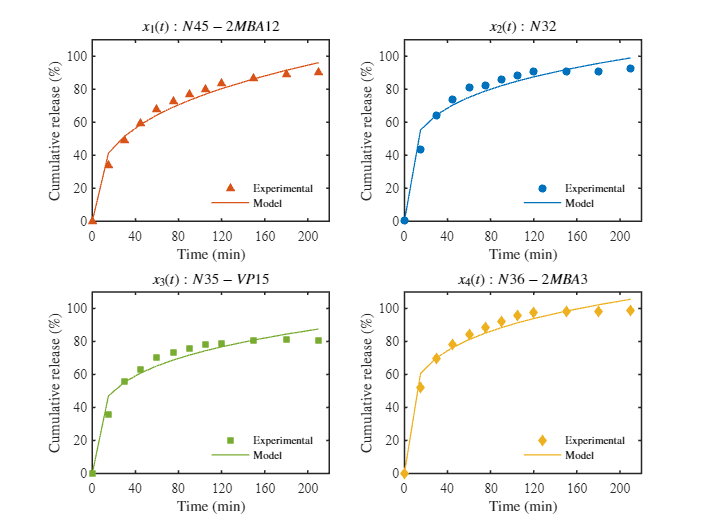

plotresults(t,xo,xp); exportgraphics(gcf, 'results_subplots.pdf', 'ContentType', 'vector');

### Función farmacocinética de primer orden

beta0 = 100; k0 = 0.01; xfc = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel ',string(labels(i))])
    mdl = farmacocinetica(t,xo(:,i),[beta0;k0]);
    xfc(:,i) = mdl.Fitted; disp('');
end

    "Resultados para el Hidrogel "    "x1(t):N45-2MBA12"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}       87.901       1.4279       3.1816      84.719      91.083    3.1113e-14
     {'k'   }     0.025648    0.0014571    0.0032466    0.022402    0.028895      7.45e-09

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9917
Suma residual de cuadrados:     65.7818
Criterio de inf

    "Resultados para el Hidrogel "    "x2(t):N32"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE           MoE              CI95             Pvalue  
    __________    ________    _________    _________    __________________    __________

     {'beta'}       90.154      0.83826       1.8678    88.287      92.022    1.1839e-16
     {'k'   }     0.040324    0.0017609    0.0039236    0.0364    0.044247    5.6926e-10

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9952
Suma residual de cuadrados:     38.7462
Criterio de inf. Akaike

    "Resultados para el Hidrogel "    "x3(t):N35-VP15"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}       79.621       0.6482       1.4443      78.176      81.065    3.1379e-17
     {'k'   }     0.037411    0.0013631    0.0030371    0.034374    0.040448    9.5511e-11

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9967
Suma residual de cuadrados:     21.5797
Criterio de inf

    "Resultados para el Hidrogel "    "x4(t):N36-2MBA3"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}        96.21       1.3965       3.1116      93.098      99.321    1.0118e-14
     {'k'   }     0.042098    0.0029501    0.0065733    0.035525    0.048671    5.6423e-08

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9877
Suma residual de cuadrados:     111.6941
Criterio de in

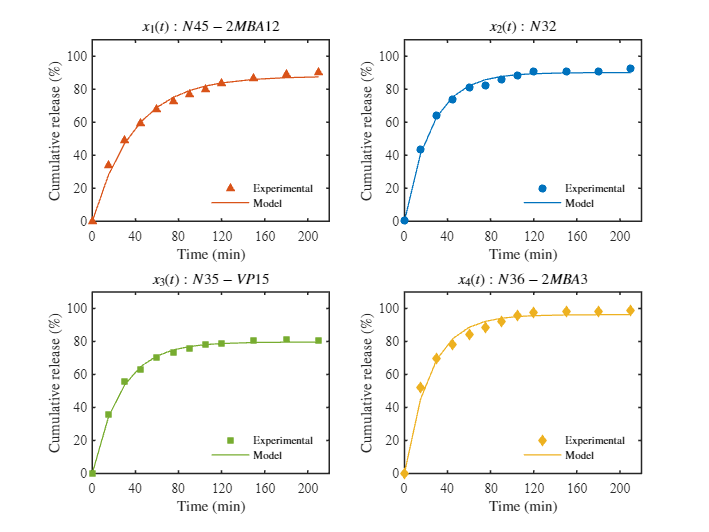

plotresults(t,xo,xfc); exportgraphics(gcf, 'farmacocinetica.pdf', 'ContentType', 'vector');

### Eureqa: Función en el tiempo

rho0 = 28.08; rho1 = 52.13; xeu = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel ',string(labels(i))])
    mdl = eureqa(t,xo(:,i),[rho0;rho1]);
    xeu(:,i) = mdl.Fitted; disp('');
end

    "Resultados para el Hidrogel "    "x1(t):N45-2MBA12"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate      SE        MoE            CI95            Pvalue  
    __________    ________    _______    ______    ________________    __________

     {'rho0'}      26.421     0.86515    1.9277    24.493    28.348    3.3217e-11
     {'rho1'}      46.187      3.7587    8.3749    37.812    54.562    2.3369e-07

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9894
Suma residual de cuadrados:     83.9945
Criterio de inf. Akaike (AICc): 62.7380

    "Resultados para el Hidrogel "    "x2(t):N32"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate      SE       MoE            CI95            Pvalue  
    __________    ________    ______    ______    ________________    __________

     {'rho0'}      25.944     2.2441    5.0001    20.944    30.944    4.1439e-07
     {'rho1'}      36.109     9.7495    21.723    14.386    57.833     0.0040836

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9304
Suma residual de cuadrados:     565.1215
Criterio de inf. Akaike (AICc): 85.6135

    "Resultados para el Hidrogel "    "x3(t):N35-VP15"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate      SE       MoE            CI95            Pvalue  
    __________    ________    ______    ______    ________________    __________

     {'rho0'}      23.212     1.8894    4.2098    19.003    27.422    2.3405e-07
     {'rho1'}      33.997     8.2085     18.29    15.708    52.287     0.0020063

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9379
Suma residual de cuadrados:     400.5859
Criterio de inf. Akaike (AICc): 81.4841

    "Resultados para el Hidrogel "    "x4(t):N36-2MBA3"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate      SE       MoE            CI95           Pvalue  
    __________    ________    ______    ______    ________________    _________

     {'rho0'}      27.414     2.3868    5.3182    22.096    32.732    4.407e-07
     {'rho1'}      36.756      10.37    23.105    13.651    59.862    0.0053161

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9295
Suma residual de cuadrados:     639.3133
Criterio de inf. Akaike (AICc): 87.0937

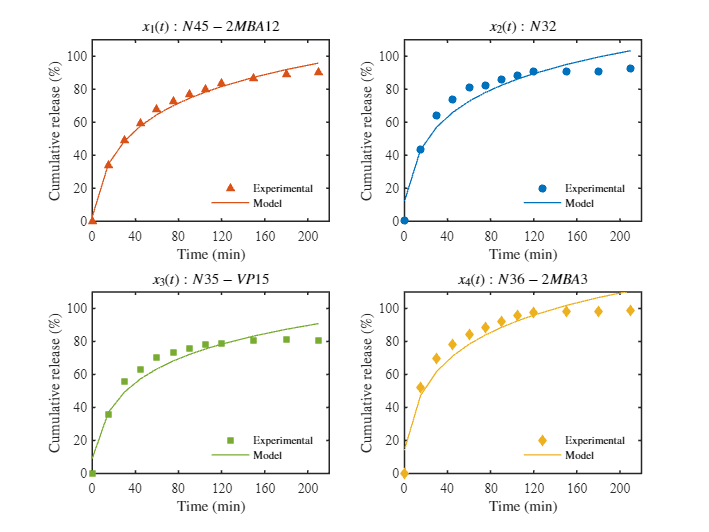

plotresults(t,xo,xeu); exportgraphics(gcf, 'eureqa.pdf', 'ContentType', 'vector');

### Eureqa: Farmacocinética de primer orden

rho0 = 2.27108381375622; 
rho1 = 0.0256385609401562; 

% Inicializar matriz para guardar los valores ajustados
[n_filas, n_cols] = size(xo);
xeu2 = zeros(n_filas, n_cols);

% Bucle de evaluación para cada hidrogel
for i = 1:4
    disp(['Resultados para el Hidrogel ', string(labels(i))])
    
    % Llamar a la función, pasando el tiempo 't', los datos 'xo(:,i)' y los parámetros
    mdl = eureqa2(t, xo(:,i), [rho0; rho1]);
    
    % Extraer los valores simulados/ajustados (la trayectoria resuelta)
    xeu2(:,i) = mdl.Fitted; 
end

    "Resultados para el Hidrogel "    "x1(t):N45-2MBA12"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'rho0'}       2.2542      0.10283      0.22913      2.0251      2.4833    8.7406e-10
     {'rho1'}     0.025644    0.0014563    0.0032448    0.022399    0.028889    7.4205e-09

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9917
Suma residual de cuadrados:     65.7116
Criterio de inf

    "Resultados para el Hidrogel "    "x2(t):N32"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'rho0'}       3.6247      0.13873      0.30912      3.3156      3.9338    1.5533e-10
     {'rho1'}     0.040198    0.0017429    0.0038834    0.036315    0.044081    5.3044e-10

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9953
Suma residual de cuadrados:     38.0485
Criterio de inf

    "Resultados para el Hidrogel "    "x3(t):N35-VP15"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'rho0'}       2.9735     0.094053      0.20956      2.7639      3.1831    2.3567e-11
     {'rho1'}     0.037342    0.0013545    0.0030181    0.034323     0.04036    9.1422e-11

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9967
Suma residual de cuadrados:     21.3390
Criterio de inf

    "Resultados para el Hidrogel "    "x4(t):N36-2MBA3"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE          MoE               CI95              Pvalue  
    __________    ________    ________    _________    ____________________    __________

     {'rho0'}      4.0441      0.25131      0.55996      3.4842      4.6041    1.7765e-08
     {'rho1'}     0.04203     0.002939    0.0065484    0.035482    0.048579    5.5256e-08

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9878
Suma residual de cuadrados:     111.0133
Criterio de inf. A

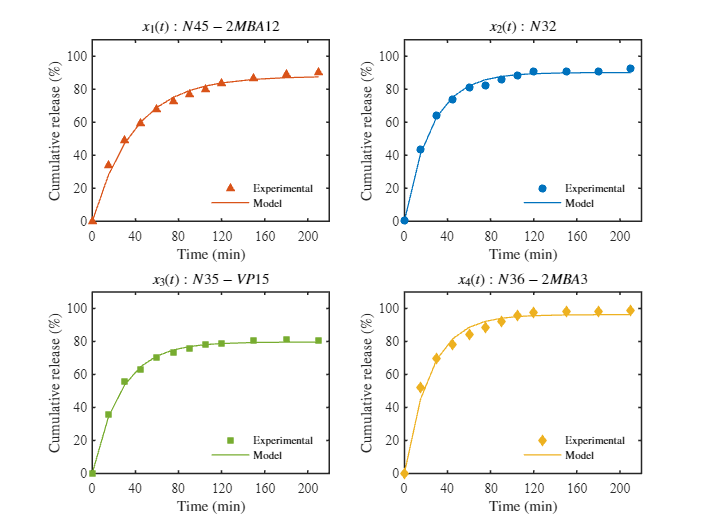

plotresults(t,xo,xeu2); exportgraphics(gcf, 'eureqa2.pdf', 'ContentType', 'vector');

## Funciones

### Datos experimentales

function [t, x1, x2, x3, x4] = getdata(data)
    sys = readmatrix(data);
    t = sys(:,1); x1 = sys(:,2); x2 = sys(:,3); x3 = sys(:,4); x4 = sys(:,5);
    T = array2table([t,x1,x2,x3,x4],'VariableNames',{'t [min]','N45','N32','N35','N36'}); disp(T);
end

function plotdata(t, x1, x2, x3, x4)
    % Crear la figura y configurar el fondo
    set(figure(), 'Color', 'w')
    
    % Definir tamaño de fuente base
    FS = 12;
    
    % Configurar el tamaño y posición de la ventana en centímetros
    set(gcf, 'Units', 'Centimeters', 'Position', [1, 1, 20, 12])
    
    % Configurar los ejes (sin subplots, todo en la misma gráfica)
    hold on, box on, grid off;
    
    % Configuraciones de las series
    nombresLeyenda = {'$x_1(t): N45-2MBA12$', '$x_2(t): N32$', '$x_3(t): N35-VP15$', '$x_4(t): N36-2MBA3$'};
    marcadores = {'^', 's', 'o', 'd'}; 
    colores = {'#D95319', '#0072BD', '#77AC30', '#EDB120'}; 
    variables_x = {x1, x2, x3, x4};
    
    % Graficar usando un bucle
    for i = 1:4
        plot(t, variables_x{i}, ...
            'LineStyle', 'none', ...
            'Marker', marcadores{i}, ...
            'MarkerFaceColor', colores{i}, ...
            'MarkerEdgeColor', colores{i}, ...
            'MarkerSize', 6);
    end
    
    % Etiquetas usando el intérprete de LaTeX (nota el \% para el porcentaje)
    xlabel('Time (min)', 'Interpreter', 'Latex', 'FontSize', FS)
    ylabel('Cumulative drug release (\%)', 'Interpreter', 'Latex', 'FontSize', FS)
    
    % Límites y marcas de los ejes
    xlim([0, 220]);
    ylim([0, 100]);
    xticks(0:20:220);
    yticks(0:20:100);
    
    % Configurar la leyenda con LaTeX
    legend(nombresLeyenda, 'Location', 'southeast', 'Box', 'off', ...
           'Interpreter', 'Latex', 'FontSize', FS-1);
    
    % Aplicar estilo general a los ejes (Fuente, tamaño y marcas hacia adentro)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS, ...
             'TickDir', 'in', 'LineWidth', 1.2)
             
    hold off;
    
    % --- Exportar la gráfica a PDF ---
    nombreArchivoPDF = 'data.pdf';
    exportgraphics(gcf, nombreArchivoPDF, 'ContentType', 'vector');
    disp(['--> Gráfica exportada exitosamente como: ', nombreArchivoPDF]);
end

function plotresults(t, xo, xp)
    % plotresults Grafica datos experimentales vs predicciones en subplots 2x2
    
    % --- 1. CONFIGURACIÓN DE LA FIGURA ---
    set(figure(), 'Color', 'w')
    
    % Definir tamaño de fuente base y un tamaño de figura más alto para 2x2
    FS = 11; 
    set(gcf, 'Units', 'Centimeters', 'Position', [1, 1, 20, 15])
    
    % Nombres, marcadores y colores
    nombresTitulo = {'$x_1(t): N45-2MBA12$', '$x_2(t): N32$', '$x_3(t): N35-VP15$', '$x_4(t): N36-2MBA3$'};
    marcadores = {'^', 'o', 's', 'd'}; 
    colores = {'#D95319', '#0072BD', '#77AC30', '#EDB120'}; 
    
    num_series = size(xo, 2);
    
    % --- 2. BUCLE PARA CREAR LOS SUBPLOTS ---
    for i = 1:num_series
        % Crear subplot en cuadrícula 2x2, posición i
        subplot(2, 2, i);
        hold on, box on, grid off;
        
        % A. Graficar Predicción del Modelo (LÍNEA CONTINUA)
        h_model = plot(t, xp(:, i), ...
            'LineStyle', '-', ...
            'Color', colores{i}, ...
            'LineWidth', 1);
            
        % B. Graficar Datos Experimentales (PUNTOS DISCRETOS)
        h_data = plot(t, xo(:, i), ...
            'LineStyle', 'none', ...
            'Marker', marcadores{i}, ...
            'MarkerFaceColor', colores{i}, ...
            'MarkerEdgeColor', colores{i}, ...
            'MarkerSize', 6);
            
        % --- 3. FORMATO INDIVIDUAL DE CADA SUBPLOT ---
        % Título de la sub-gráfica con el nombre del hidrogel
        title(nombresTitulo{i}, 'Interpreter', 'Latex', 'FontSize', FS+2);
        
        % Etiquetas de los ejes
        xlabel('Time (min)', 'Interpreter', 'Latex', 'FontSize', FS)
        ylabel('Cumulative release (\%)', 'Interpreter', 'Latex', 'FontSize', FS)
        
        % Límites y marcas
        xlim([0, 220]); ylim([0, 110]);
        xticks(0:40:220); 
        yticks(0:20:110);
        
        % Leyenda local para cada subplot
        legend([h_data, h_model], {'Experimental', 'Model'}, ...
               'Location', 'southeast', 'Box', 'off', ...
               'Interpreter', 'Latex', 'FontSize', FS-2);
        
        % Estilo general final de los ejes
        set(gca, 'FontName', 'Times New Roman', 'FontSize', FS, ...
                 'TickDir', 'in', 'LineWidth', 1.2)
                 
        hold off;
    end
    
end


### Modelos matemáticos y bioestadísticos

function mdl = peppas(to, xo, par)
    % Función del modelo de Korsmeyer-Peppas
    function x = model(par, t)
        k = par(1); 
        n = par(2);
        x = k * t.^n;
    end

    % Ajuste no lineal
    mdl = fitnlm(to, xo, @model, par);
    
    % Definir los nombres de los 2 parámetros
    Parameters = {'k'; 'n'};
    
    % Llamar a la función de estadísticas
    biostats(mdl, Parameters);
end

function mdl = farmacocinetica(to, xo, par)
    % Función del modelo de farmacocinetica
    function x = model(par, t)
        beta = par(1); 
        k = par(2);
        x = beta*(1-exp(-k*t));
    end

    % Ajuste no lineal
    mdl = fitnlm(to, xo, @model, par);
    
    % Definir los nombres de los 2 parámetros
    Parameters = {'beta'; 'k'};
    
    % Llamar a la función de estadísticas
    biostats(mdl, Parameters);
end

function mdl = eureqa(to, xo, par)
    % Función del modelo de eureqa
    function x = model(par, t)
        rho0 = par(1);
        rho1 = par(2);
        x = rho0*log(6.39833203426026 + t) - rho1;
    end

    % Ajuste no lineal
    mdl = fitnlm(to, xo, @model, par);
    
    % Definir los nombres de los 2 parámetros
    Parameters = {'rho0'; 'rho1'};
    
    % Llamar a la función de estadísticas
    biostats(mdl, Parameters);
end

function mdl = eureqa2(t_data, x1_data, par_inicial)
    
    % Condición inicial (el valor medido en t=0)
    x0_val = x1_data(1); 

    % 1. Definir la función que resolverá la EDO para los parámetros iterados
    function x_pred = solve_ode(par, t)
        p0 = par(1); % rho0
        p1 = par(2); % rho1
        
        % Ecuación diferencial: D(x1, t, 1) = p0 - p1*x1
        ode_fun = @(t_dummy, x) p0 - p1 * x;
        
        % AJUSTE CRÍTICO: Reducir las tolerancias para que fitnlm 
        % pueda calcular los gradientes correctamente.
        options = odeset('RelTol', 1e-8, 'AbsTol', 1e-10);
        
        % Resolver la EDO forzando la salida en los instantes 't'
        [~, x_sim] = ode45(ode_fun, t, x0_val, options);
        
        % Asegurar formato de vector columna
        x_pred = x_sim(:);
    end

    % 2. Ajuste estadístico comparando los datos reales vs la simulación
    mdl = fitnlm(t_data, x1_data, @solve_ode, par_inicial);
    
    % 3. Imprimir estadísticas
    Parameters = {'rho0'; 'rho1'};
    
    % Manejo de errores por si biostats no está en la carpeta actual
    try
        biostats(mdl, Parameters);
    catch
        disp('Ajuste completado. (Nota: función biostats no encontrada).');
    end
end

function biostats(mdl, Parameters)
    % Extraer coeficientes y errores estándar
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    
    % Nivel de significancia y cálculo de intervalos
    alpha = 0.05;
    CI95 = coefCI(mdl, alpha);
    
    % Extraer los bioestadísticos solicitados
    n_datos = mdl.NumObservations;      % Cantidad de datos
    n_params = mdl.NumCoefficients;     % Cantidad de parámetros
    dof = mdl.DFE;                      % Grados de libertad
    tval = tinv(1 - alpha/2, dof);      % Valor t-student
    MoE = SE * tval;                    % Margen de error
    
    % Crear la tabla de resultados 
    Results = table(Parameters, Estimate, SE, MoE, CI95, Pvalue);
    
    % Extraer métricas de bondad de ajuste
    R2o = mdl.Rsquared.Ordinary;        % R-cuadrada ordinaria
    SSE = mdl.SSE;                      % Suma residual de cuadrados
    AICc = mdl.ModelCriterion.AICc;     % Criterio de Akaike ajustado
    
    fprintf('Cantidad de datos (n):          %d\n', n_datos);
    fprintf('Cantidad de parámetros (k):     %d\n', n_params);
    fprintf('Grados de libertad (DFE):       %d\n', dof);
    fprintf('Significancia (alpha):          %.2f\n', alpha);
    fprintf('Valor t-student:                %.4f\n', tval);
    disp('-------------------------------------------------------------');
    disp('Coefficients:');
    disp(Results);
    disp('-------------------------------------------------------------');
    disp('Bondad de Ajuste:');
    fprintf('R-cuadrada ordinaria:           %.4f\n', R2o);
    fprintf('Suma residual de cuadrados:     %.4f\n', SSE);
    fprintf('Criterio de inf. Akaike (AICc): %.4f\n', AICc);
    disp('=============================================================');
end

